clear;clc;

- **实验计算**

%%%%%%%%%实验条件%%%%%%%%%
f0=1000000000;
Z0=50;
omiga0=2*pi*f0;
L=0.00000001;
ZL0=10+1i*2*pi*f0*L;
%%%%%%%%%频带（转成数组形式）%%%%%%%%%
alpha=0.6:0.001:1.4;
f=f0.*alpha;
omiga=2.*pi.*f0.*alpha;
ZL=10+1i.*2.*pi.*f.*L;
%%%%%%%%%由圆图得到电路设计%%%%%%%%%
%结构1-先串电容，再并电感
C1=1.920*10^(-12);
L1=3.986*10^(-9);
Zin1=add_sercap(C1, omiga, ZL);
Zin2=add_parind(L1,omiga,Zin1);
gamma1=(Zin2-Z0)./(Zin2+Z0);
%结构2-先并电容，再串电感
C2=3.5140*10^(-12);
L2=21.252*10^(-9);
Zin3=add_parcap(C2, omiga, ZL);
Zin4=add_serind(L2, omiga, Zin3);
gamma2=(Zin4-Z0)./(Zin4+Z0);
%结构3-先串电容，再并电容
C3=3.714*10^(-12);
C4=6.370*10^(-12);
Zin5=add_sercap(C3, omiga, ZL);
Zin6=add_parcap(C4,omiga,Zin5);
gamma3=(Zin6-Z0)./(Zin6+Z0);
%结构4-先并电容，再串电容
C5=1.427*10^(-12);
C6=1.194*10^(-12);
Zin7=add_parcap(C5,omiga,ZL);
Zin8=add_sercap(C6, omiga, Zin7);
gamma4=(Zin8-Z0)./(Zin8+Z0);

- **绘制图像**

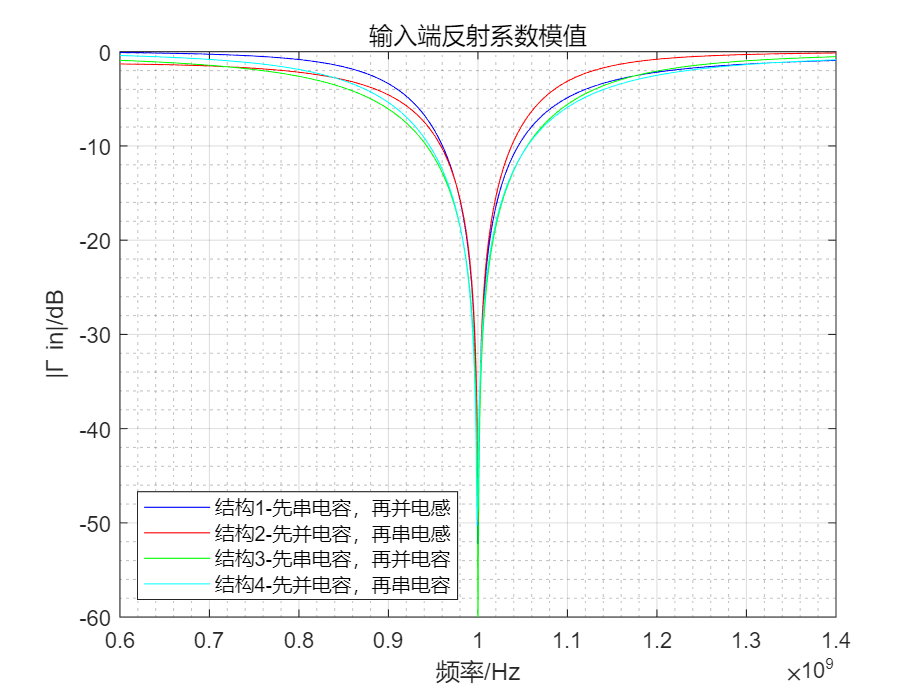

%% 反射系数频率响应曲线绘制
err = 1e-9;
%单分支并联短截线的两个解
figure(1);
plot(f,20*log10(abs(gamma1)+err),'b');    %第一解反射系数曲线模值频率特性
hold on;
plot(f,20*log10(abs(gamma2)+err),'r');    %第二解反射系数曲线模值频率特性
hold on;
plot(f,20*log10(abs(gamma3)+err),'g');    %第一解反射系数曲线模值频率特性
hold on;
plot(f,20*log10(abs(gamma4)+err),'c');    %第二解反射系数曲线模值频率特性
%%%%%%%%%%%%%%%%%%%
title('输入端反射系数模值');
lgd=legend("结构1-先串电容，再并电感","结构2-先并电容，再串电感","结构3-先串电容，再并电容","结构4-先并电容，再串电容");
lgd.Location = 'southwest';
xlabel('频率/Hz');
ylabel('|Γ_ in|/dB');
ylim([-60 0]);
grid on; grid minor;

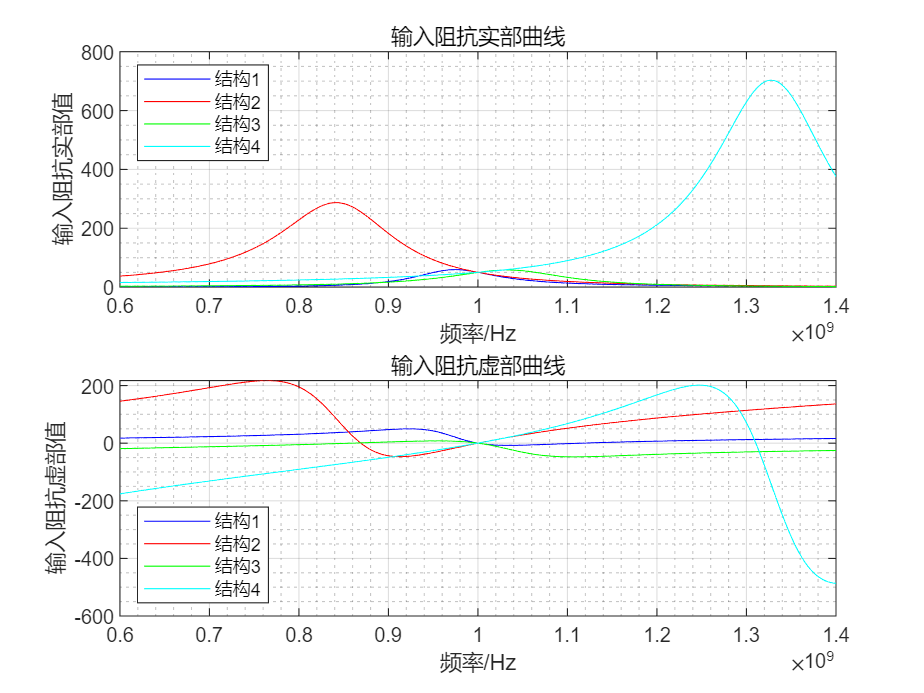

%% 输入阻抗频率响应曲线绘制
figure(2);
subplot(2,1,1);
plot(f,real(Zin2),'b');                     %输入阻抗实部频率特性
hold on
plot(f,real(Zin4),'r'); 
hold on
plot(f,real(Zin6),'g');                     
hold on
plot(f,real(Zin8),'c'); 
%%%%%%%%%%%%%%%%%%%
title('输入阻抗实部曲线');
lgd=legend("结构1","结构2","结构3","结构4");
lgd.Location = 'northwest';
xlabel('频率/Hz');
ylabel('输入阻抗实部值');
grid on; grid minor;
subplot(2,1,2)                                 %输入阻抗虚部频率特性
plot(f,imag(Zin2),'b'); 
hold on
plot(f,imag(Zin4),'r'); 
hold on
plot(f,imag(Zin6),'g'); 
hold on
plot(f,imag(Zin8),'c'); 
%%%%%%%%%%%%%%%%%%%
title('输入阻抗虚部曲线');
lgd=legend("结构1","结构2","结构3","结构4");
lgd.Location = 'southwest';
xlabel('频率/Hz');
ylabel('输入阻抗虚部值');
grid on; grid minor;

- **函数add_parcap，阻抗Z_L串联电感L**

function [Zin] = add_parcap(cap, omiga, ZL)	
    Z_temp=-1i./cap./omiga;
    Zin=Z_temp.*ZL./(Z_temp+ZL);
end

- **函数add_parind，阻抗Z_L串联电容C**

function [Zin] = add_parind(ind, omiga, ZL)	
    Z_temp=1i.*ind.*omiga;
    Zin=Z_temp.*ZL./(Z_temp+ZL);
end

- **函数add_sercap，阻抗Z_L并联电感L**

function [Zin] = add_sercap(cap, omiga, ZL)	
    Zin = ZL - 1i./omiga./cap;
end

- **函数add_serind，阻抗Z_L并联电容C**

function [Zin] = add_serind(ind, omiga, ZL)	
    Zin = ZL + 1i.*omiga.*ind;
end